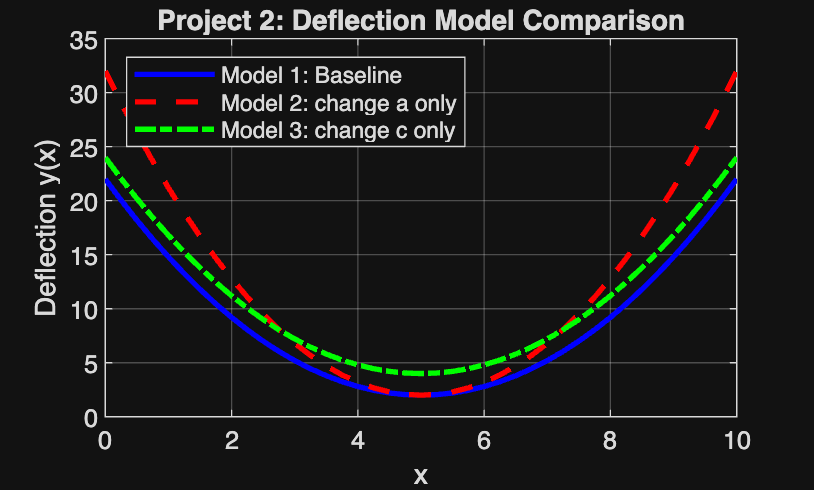

%{
ES115 - Control Panel Class Project
Author: Nivea Williamson
Version: 1.0
Date: 2026-04-20

Purpose:
    Model beam deflection using a quadratic equation with parameters
    (a, b, c), compare three models, plot them on one figure, and
    identify the minimum deflection location for each model.

Input:
    - x values from 0 to 10 in steps of 0.25
    - Baseline parameters a, b, c
    - Two alternative models changing one parameter at a time

Output:
    - Plot of all three models on one graph
    - Minimum deflection value and location for each model
    - Table summarizing results

Engineering Algorithms:
    - Define the x-domain
    - Choose realistic baseline parameters for the quadratic model
    - Create two new models by changing only one parameter at a time
    - Evaluate all models over the domain
    - Plot all models on one figure with a legend
    - Use MATLAB to find the minimum deflection location for each model
    - Display results in a table

MATLAB Tools/Functions:
    - plot()
    - hold on
    - grid on
    - title()
    - xlabel()
    - ylabel()
    - legend()
    - min()
    - table()
    - disp()
%}

%% PROJECT 2

clc;
clear;

% Domain
x = 0:0.25:10;

% Baseline model parameters
a1 = 0.8;
b1 = 5;
c1 = 2;

% Model 2: change a only
a2 = 1.2;
b2 = b1;
c2 = c1;

% Model 3: change c only
a3 = a1;
b3 = b1;
c3 = 4;

% Define the three models
y1 = a1*(x - b1).^2 + c1;
y2 = a2*(x - b2).^2 + c2;
y3 = a3*(x - b3).^2 + c3;

% Plot all models
plot(x, y1, 'b-', 'LineWidth', 2)
hold on;
plot(x, y2, 'r--', 'LineWidth', 2)
plot(x, y3, 'g-.', 'LineWidth', 2)

title('Project 2: Deflection Model Comparison')
xlabel('x')
ylabel('Deflection y(x)')
legend('Model 1: Baseline', 'Model 2: change a only', 'Model 3: change c only', ...
    'Location', 'northwest')
grid on;


% Find minimum deflection value and location for each model
[min_y1, idx1] = min(y1);
[min_y2, idx2] = min(y2);
[min_y3, idx3] = min(y3);

min_x1 = x(idx1);
min_x2 = x(idx2);
min_x3 = x(idx3);

% Display results
fprintf('Model 1 minimum deflection = %.2f at x = %.2f\n', min_y1, min_x1);

Model 1 minimum deflection = 2.00 at x = 5.00


fprintf('Model 2 minimum deflection = %.2f at x = %.2f\n', min_y2, min_x2);

Model 2 minimum deflection = 2.00 at x = 5.00


fprintf('Model 3 minimum deflection = %.2f at x = %.2f\n', min_y3, min_x3);

Model 3 minimum deflection = 4.00 at x = 5.00



% Create results table
Model = ["Model 1"; "Model 2"; "Model 3"];
a_values = [a1; a2; a3];
b_values = [b1; b2; b3];
c_values = [c1; c2; c3];
Min_Deflection = [min_y1; min_y2; min_y3];
X_at_Min = [min_x1; min_x2; min_x3];

T = table(Model, a_values, b_values, c_values, Min_Deflection, X_at_Min);

disp(T);

      Model      a_values    b_values    c_values    Min_Deflection    X_at_Min
    _________    ________    ________    ________    ______________    ________

    "Model 1"      0.8          5           2              2              5    
    "Model 2"      1.2          5           2              2              5    
    "Model 3"      0.8          5           4              4              5    

